## EXPALTS: ALTERNATIVE NATURAL EXPONENTIAL COMPUTATIONS

`Oluwasegun Somefun (OAS)`

`<oasomefun@futa.edu.ng, somefuno@oregonstate.edu>. 2021.`

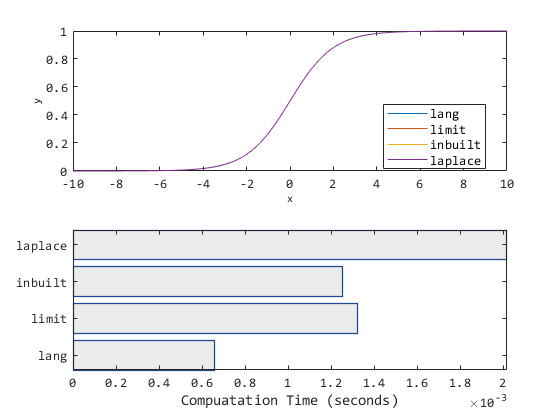

% UseCase: Test

x = (-10:0.01:10)';

% - inbuilt
tic; y = 1./(1+exp(-x)); t = toc;
% %
tic; y0 = 1./(1+expalts.bones(-x, 0)); t0 = toc;
tic; y1 = 1./(1+expalts.bones(-x, 1)); t1 = toc; 
tic; y2 = 1./(1+expalts.bones(-x, 2)); t2 = toc;
%
% Plots
tlay = tiledlayout('flow');
nexttile; plot(x,[y y0 y1 y2]);
legend({'lang','limit','inbuilt','laplace'},...
    'FontName','Consolas', 'FontSize',10,'Location',"best");
ax = gca; ax.XScale = 'linear'; ax.YScale = 'linear';
ax= gca; ax.FontName = 'Consolas'; ax.FontSize=10;
ylabel("y",'FontName','Consolas', 'FontSize',8);
xlabel("x",'FontName','Consolas', 'FontSize',8);
%
nexttile; b= barh([t t0 t1 t2]);
b(1).FaceColor = [.6 .6 .6];
b(1).FaceAlpha = 0.2;
b(1).EdgeColor = [.13 .28 .58];
b(1).LineWidth = 1;
b(1).BarWidth = 0.8;
b(1).Clipping = "on";
xlabel("Compuatation Time (seconds)",'FontName','Consolas', 'FontSize',10);
% 'lang-opt': Language Optimized
yticklabels({'lang-opt','limit','inbuilt','laplace'})
ax= gca; ax.FontName = 'Consolas'; ax.FontSize=10;
axis("tight")